# Pool fire modelization example 

In this example, we will introduce the several functions implemented for pool fire modelization. 

clear
clc

## 1. Initialization of model parameters 

V = 100   ; % pool volume  m3
h_desntity = 719 ; % density of flamable substance kg/m3
vap_heat = 370 ;      % vaporization heat of flamable substance Kj/Kg
comb_heat= 45000;       % combustion heat of flamable substance Kj/Kg
spec_heat_cap = 2.21 ; % specific heat capacity Cp of flamable substance kj/kg/k
T_boiling = 423 ; % boiling temperature of flamable substance -  Kelvins 
radiation_fraction = 0.2 ; % [0-1]
pool_diameter = 42.4 ; % m 
wind_vel = 5; % wind speed - [0 , inf]  m/s 
T_ambiant = 298 ; % Ambiant temperature -  Kelvins 
air_density = 1.21 ; % Density of air -  kg/m3 
air_viscosity = 16.7 ; % Dynamic viscosity of air - uPa.s
RH = 0.7 ; % humidity ratio [0-1]
P_ow = 2320 ; % saturation vapor pressure ;
N0 =0; % population density in the area - ppl / m²

**Resolution of computations for heatflux & thermal effects  :** A higher value => smaller step => slower execution 

Indicative values :  125  - 250 - 500 

Resolution = 125 ; % 125 250 500 

**Body coverage : ** Impact of clothes on thermal radiation :  

0.94  : summer clothes  - small mitigation 

0.14 : winter clothes - mitigation 

1 : ignore clothes impact

Fk = 1 ;% body coverage / clothes - reduction of thermal effects on bodies - 0.94 : summer clothes 0.14 winter clothes  1 : no effect 


## 2. Computations 

**Burning rate & time :  **Choose one model 

- Zabetakis-Burgess Method for liquide hydrocarbons 

- Mudan method for liquified gas 

Overall, Zabetakis-Burgess is less precise but it gives a good approximation. 

eq_burn_rate & k_beta coefficients can be found in litterature. Check FIRES, EXPLOSIONS,AND TOXIC GAS DISPERSIONS - 2010 - p 81

**Burning rate in  **Kg / s  &  **time in  **s

% burning_rate = burn_rate_liq_hydrocarbon(eq_burn_rate, k_beta, pool_diameter )
  burning_rate = burn_rate_liq_gas(vap_heat,comb_heat,spec_heat_cap,T_boiling,T_ambiant);

%% burning time
burning_time = ceil(burning_time_computation(V,h_desntity,burning_rate,pool_diameter)) ;

**Flame length : If there is wind => Pritchard-Binding Method  - No wind => Thomson method **

**[meters]**

if (wind_vel > 0)
    flame_len = flame_len_wind(pool_diameter,air_density,burning_rate,wind_vel) ;
elseif (wind_vel == 0)
    flame_length = flame_len_no_wind ( pool_diameter , air_density , burning_rate  );
end

**Surface Emitting Power** : choose one method. Mudan's method is more suitable for large pools (> 15m). 

[kW/m²]

  SEP = SEP_std(radiation_fraction,flame_len,pool_diameter,burning_rate,comb_heat);
% SEP = SEP_mudan( pool_diameter)
 

**Flame tilt** : in case there is wind. 

[degrees]

tilt = tilt_computation(wind_vel,pool_diameter,air_density,air_viscosity);
 

**Compute heat flux for various distances from flame center **

**heat_flux_batch1D :  Heatflux array in kW/m²  **

**R_1D : Distances in meters **

[R_1D,heat_flux_batch1D] = batch_heat_flux_computation_1D(pool_diameter,Resolution,tilt,flame_len,RH,P_ow,SEP);
 
% curve fitting  
fit_R_f_heatflux = fit_distance_to_heatflux(heat_flux_batch1D,R_1D,0) ;

[fit_heatflux_f_R , gof]= fit_heatflux_to_distance(R_1D,heat_flux_batch1D,0) ; 

str ={formula(fit_heatflux_f_R),' parameters resp : ',num2str(coeffvalues(fit_heatflux_f_R)),'R^2 = ',gof.rsquare };


**Compute probabilities of injury for various distances using probit functions  : **

Level 1 skin burns - Level 2 - Death 

As well as overall effects : an estimation of overall deaths and injuries in the area given the population density 


[P_level1_1d_batch,P_level2_1d_batch, P_level3_1d_batch ] = batch_ppl_effect_computation_1D(Fk,R_1D,  pool_diameter , fit_R_f_heatflux  ,fit_heatflux_f_R);

ovr_injuries_lv1 = 0 ; ovr_injuries_lv2 =0;  ovr_injuries_lv3=0;
if (N0 > 0)
 [ovr_injuries_lv1,ovr_injuries_lv2,ovr_injuries_lv3] = overall_effects_computation(N0,pool_diameter,R_1D,P_level1_1d_batch,P_level2_1d_batch, P_level3_1d_batch,fit_R_f_heatflux) ;
end


**If there is no wind, a )**

**This feature is not available in windy conditions, because view-factors models featured in this project only apply for down wind direction, and can't be generalized over 360°...**


if(wind_vel == 0) 
    
    [X , Y , heat_flux_batch2D] = batch_heat_flux_computation_2D(pool_diameter,Resolution,tilt,flame_len,RH,P_ow,SEP);
    
    if(N0>0)         
        [P_level1_2d_batch , P_level2_2d_batch ,  P_level3_2d_batch] = batch_ppl_effect_computation_2D(Fk, X,Y,pool_diameter , fit_R_f_heatflux  ,fit_heatflux_f_R);
    end
end

## 3. Plot results : 

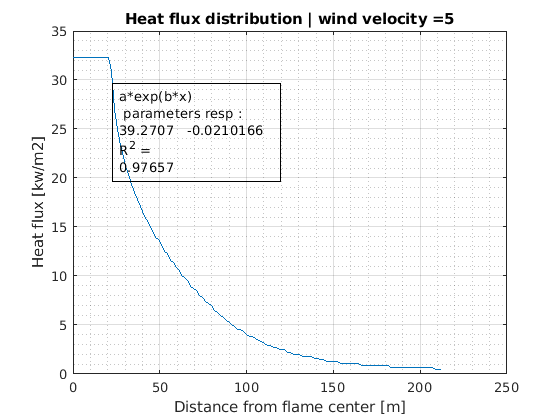

plot1Dheatflux(R_1D,heat_flux_batch1D,wind_vel,str) ;

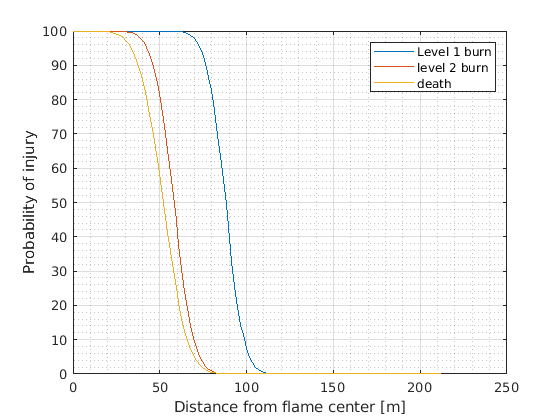

pause(1);
plot_ppl_effects(R_1D,P_level1_1d_batch,P_level2_1d_batch, P_level3_1d_batch);

pause(1);
if(wind_vel == 0)
     plot_heatmap_injuries(X,Y,P_level1_2d_batch , P_level2_2d_batch ,  P_level3_2d_batch); 
     plotHeatMap(X,Y,heat_flux_batch2D,wind_vel) ;
end
pause(1);
Sim_array = [T_ambiant ; wind_vel ; 100*RH ; pool_diameter ; burning_rate ; flame_len ; burning_time ;  N0;ovr_injuries_lv1;ovr_injuries_lv2;ovr_injuries_lv3];
fx = figure('Name','Overview');
fx.Resize = 'off';
fx.Position(3) = 800; 
fx.Position(4) = 500;
uit = uitable(fx,'Data',Sim_array,'Position',[fx.Position(1)*0.5  fx.Position(2)*0.75 fx.Position(3)*0.44 fx.Position(4)*0.465]);
uit.ColumnName = {'Value'};
uit.RowName = {'Ambiant temperature [k]','Wind velocity [m/s]','Humidity','Pool diameter [m]','Burning rate [kg/s]','Flame height [m]','Burning time [mn]','Pop density [ppl/m2]','N° level 1 burns','N° level 2 burns','N° deaths'};
